# Shakespear vs Trump Dataset

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/shakespear_trump/shakespear_trump_bge-large-en-v1.5.parquet", "SelectedVariableNames", ["text", "author", "embedding"]);

rawData.author = categorical(rawData.author);

rawData(1:8, :)

ans = 8×3 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

groupcounts(rawData, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear        472       0.82745
    trump           56571        99.173


## Preperation

sampleSize = 1000;
contamination =0.2;
shakespearIndices = find(rawData.author == "shakespear");
trumpIndices = find(rawData.author == "trump");

numShakespearSamples = round(contamination * sampleSize);
numTrumpSamples = sampleSize - numShakespearSamples;

shakespearSampleIndices = datasample(shakespearIndices, numShakespearSamples, Replace=false);
trumpSampleIndices = datasample(trumpIndices, numTrumpSamples, Replace=false);
data = rawData(sort(cat(1, shakespearSampleIndices, trumpSampleIndices)),:);

clear numShakespearSamples;
clear numTrumpSamples;
clear shakespearSampleIndices;
clear trumpSampleIndices;
clear trumpIndices;
clear shakespearIndices;
clear rawData;

groupcounts(data, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear       200          20   
    trump            800          80   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding, UniformOutput=false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.author, {'trump' 'shakespear'}, {'inlier' 'outlier'});

## Separability

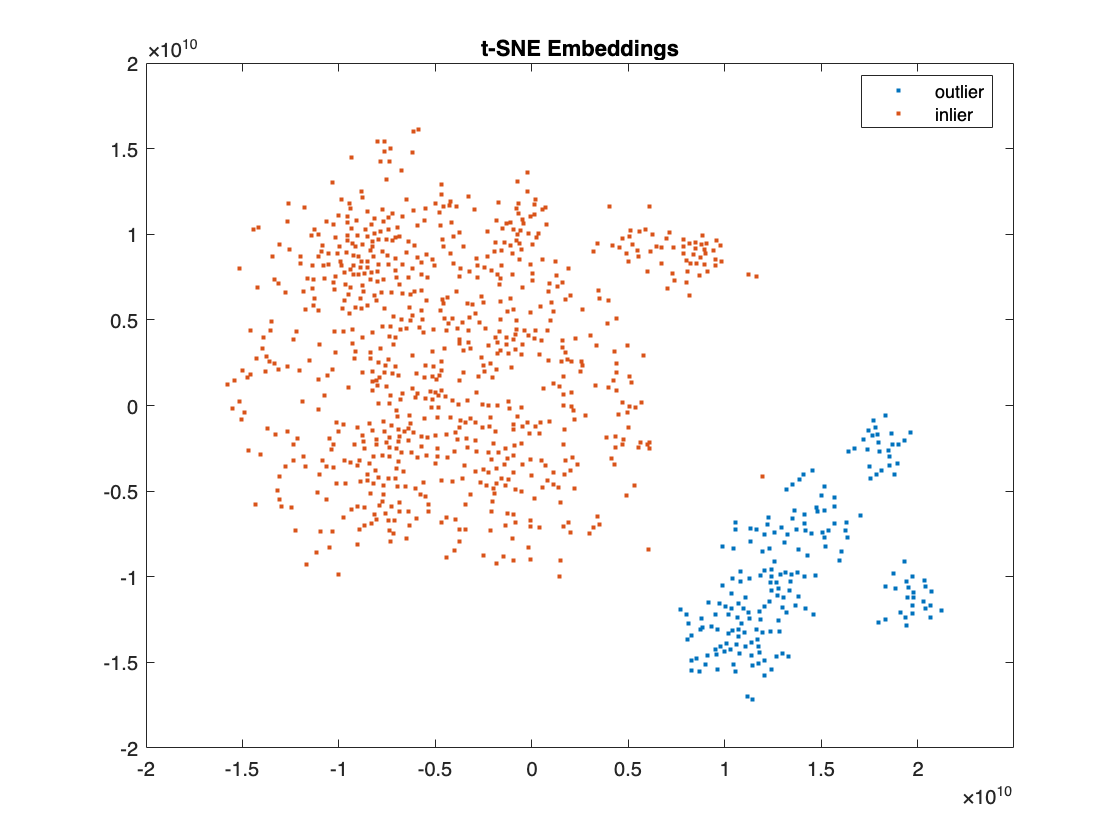

Y = tsne(unlabeledData, Distance="cosine");

figure;
gscatter(Y(:,1),Y(:,2),labels);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.9990

## Computation

alpha = 0.7;

% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 0.959313293348824


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 4, SDO
Convergence at iteration 6, SpatialRank
Convergence at iteration 5, SpatialMedian
Convergence at iteration 5, SSCM
-> Best estimator is SpatialMedian


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear       128        18.286 
    trump            572        81.714 


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "author")

ans = 2×3 table
      author      GroupCount    Percent
    __________    __________    _______

    shakespear         1        0.91743
    trump            108         99.083


### Confusion Matrix

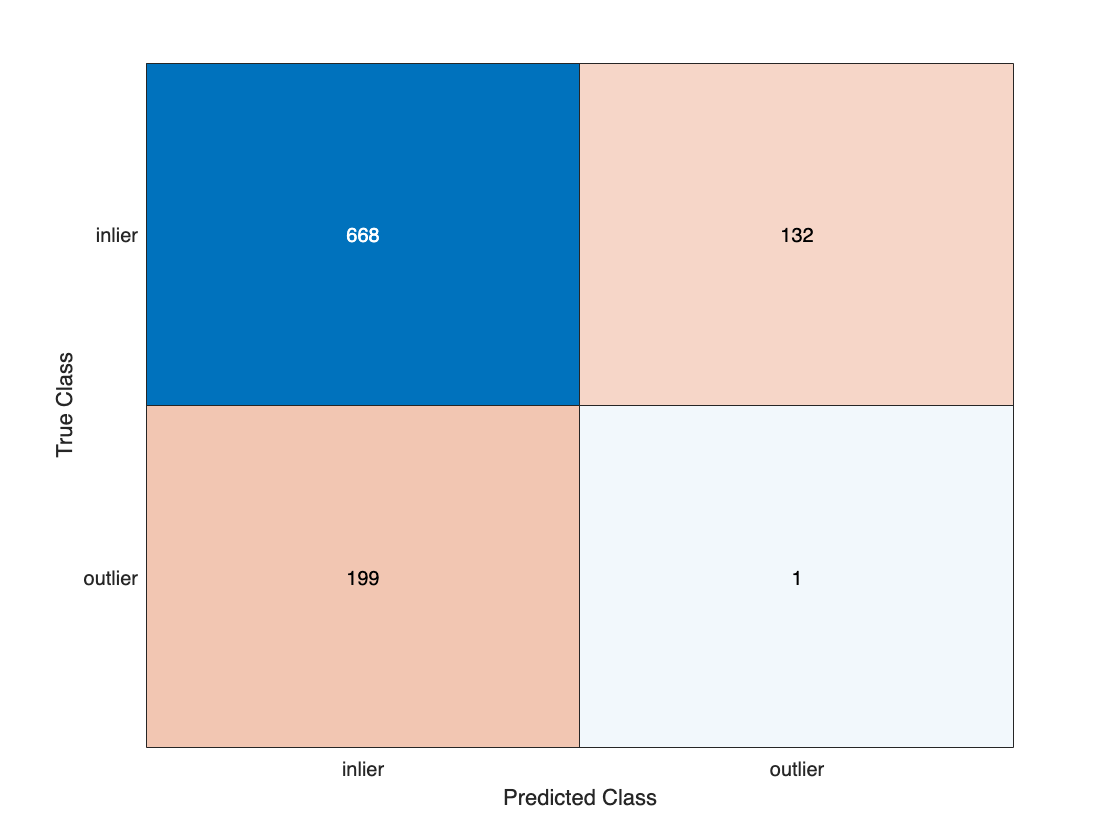

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

     0.693       0.77666        0.865          0.005       0.81845


### Mahalanobis Distances

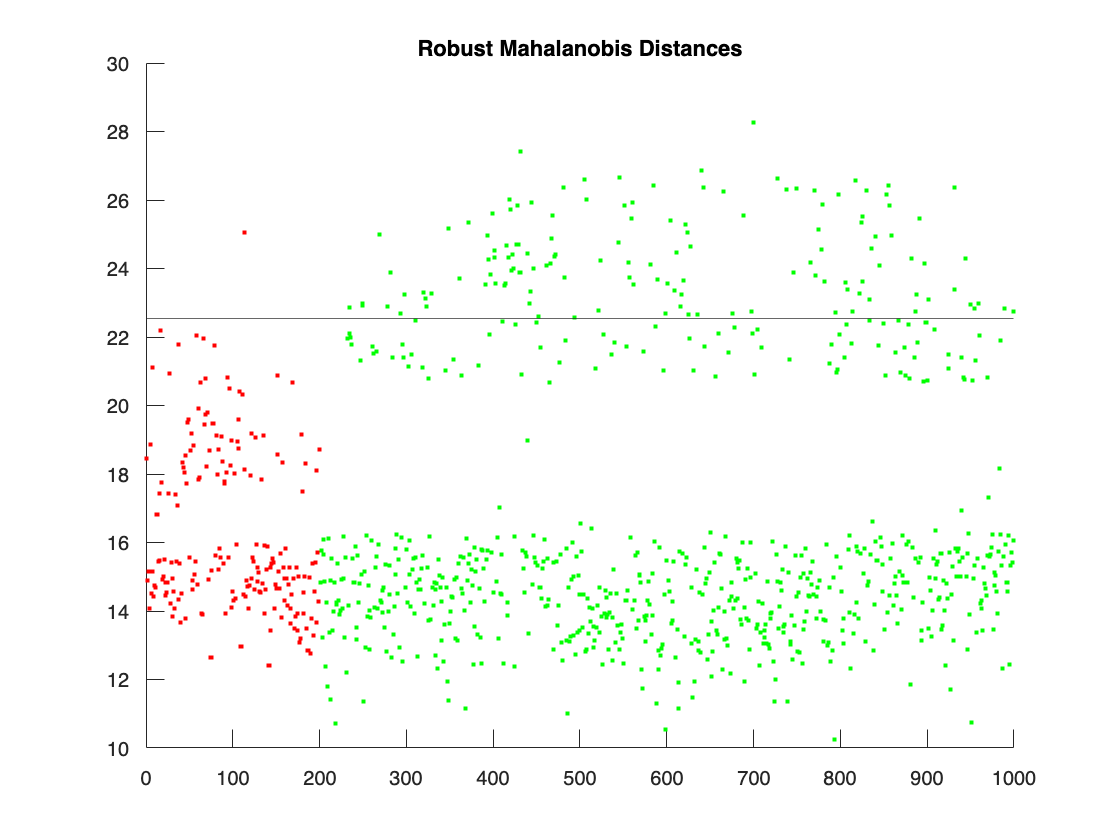

figure;
mahalchart(labels, solution.rd, solution.cutoff);

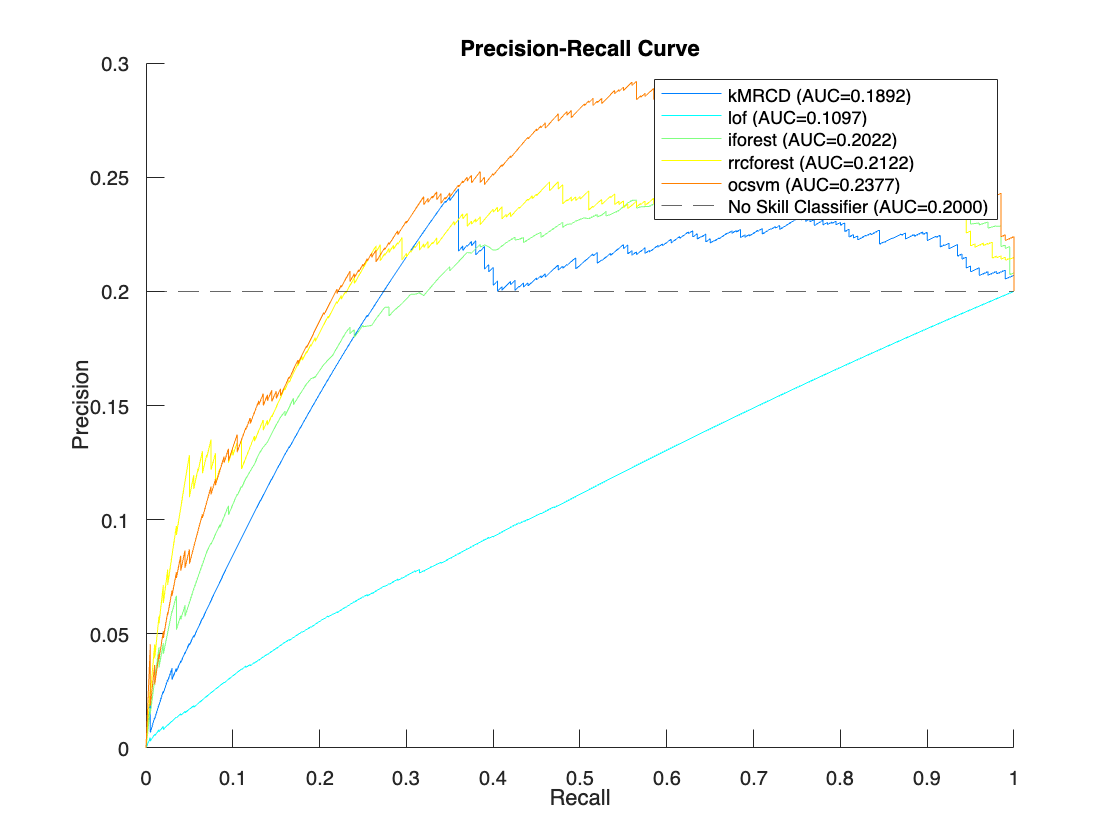

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD         0.693       0.77666         0.865         0.005       0.81845    0.18932
    lof           0.502       0.71571       0.62625         0.005         0.668    0.10974
    iforest       0.624       0.80199       0.70375         0.305       0.74967    0.20647
    rrcforest     0.628       0.80571         0.705          0.32         0.752    0.20639
    ocsvm         0.628       0.80571         0.705          0.32         0.752     0.2199


evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
objectiveplot(poc, unlabeledData);

Convergence at iteration 4, SDO
Convergence at iteration 11, SpatialRank
Convergence at iteration 11, SpatialMedian
Convergence at iteration 3, SSCM
-> Best estimator is SSCM
